                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

data = readtable('../data/data1/logvRNA.csv');

patients = unique(data.patient,'stable');
patients

patients = 6×1 cell array
    {'CHID46'}
    {'CHID77'}
    {'CHID79'}
    {'CHID32'}
    {'CHID40'}
    {'CHID08'}


num_pat = size(patients,1);


% 
% x1 = [2.0209E-7, 1.2719E-7, 0.41184, 1.52453, 41085.62299, 0.03901, 6];
% x2 = [4.1205E-7, 9.9623E-8, 0.03291, 0.51576, 11563.55961, 0.02501, 6];
% x3 = [2.0301E-7, 8.4588E-16, 0.0132, 0.97946, 29382.88451, 0.03439, 10];
% x4 = [1.1951E-6, 9.2262E-7, 0.43713, 4.15686, 10980.08977, 0.10254, 13];
% x5 = [2.9663E-7, 2.0198E-7, 0.18906, 1.34474, 23745.98087, 0.03773, 6];
% x6 = [2.0375E-8, 1.0302E-7, 0.1101, 5.23275, 781644.29827, 3.9911E-17, 21];


xx1 = [0.409*10^-6, 0.233*10^-6, 0.249, 0.775, 14.5*10^3, 0.03, 7];
xx2 = [0.431*10^-6, 0.140*10^-6, 0.077, 0.420, 10*10^3, 0.021, 24];
xx3 = [0.201*10^-6, 0.001*10^-6, 0.013, 1.048, 30.172*10^3, 0.036, 10];
xx4 = [9.203E-6, 0.011E-6, 0.013, 0.851, 0.548E3, 0.055, 12];
xx5 = [0.485E-6, 0.291E-6, 0.096, 0.803, 11.425E3, 0.033, 5];
xx6 = [0.057E-6, 0.004E-6, 0.021, 0.821, 89.892E3, 0.003, 22];


% x = [x1;x2;x3;x4;x5;x6];
x = [xx1;xx2;xx3;xx4;xx5;xx6];



best_params = zeros(num_pat,7);

tic

for i = 1:num_pat
    path = string(strcat('../data/data1/',patients(i),'.csv'))
    data_p = table2array(readtable(path));

    param = x(i,:);

    best_params(i,:) = [best_param(data_p,param), param(end)];
end 

path = "../data/data1/CHID46.csv"

path = "../data/data1/CHID77.csv"

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.028912 



path = "../data/data1/CHID79.csv"

path = "../data/data1/CHID32.csv"

path = "../data/data1/CHID40.csv"

path = "../data/data1/CHID08.csv"


toc

Elapsed time is 326.687497 seconds.


param_tb = array2table(best_params,...
            'VariableNames', ...
            {'beta0','beta_infty','k','dlt','p','d','tau'})

param_tb = 6×7 table
      beta0       beta_infty        k           dlt          p             d        tau
    __________    __________    __________    _______    __________    _________    ___

    3.0803e-07    1.7423e-07        4.7565     1.0969         24852     0.034461     7 
    4.1496e-07    8.3754e-10      0.017528    0.38585         10132     0.012231    24 
    1.5879e-07    3.5233e-10       0.01264     1.0909         39271     0.036134    10 
    2.8554e-05    8.6452e-06    4.4614e-12    0.26554        140.23      0.02066    12 
     3.445e-07    2.1395e-07       0.72065     1.3465         23536     0.035313     5 
     2.054e-08    8.4036e-08    0.00017153     1.0375    2.8248e+05    0.0020492    22 



writetable(param_tb, 'best_params_mat_2.csv')

best_params

best_params = 1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.2485    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.1013    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.3927    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0014    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.2354    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    2.8248    0.0000    0.0002


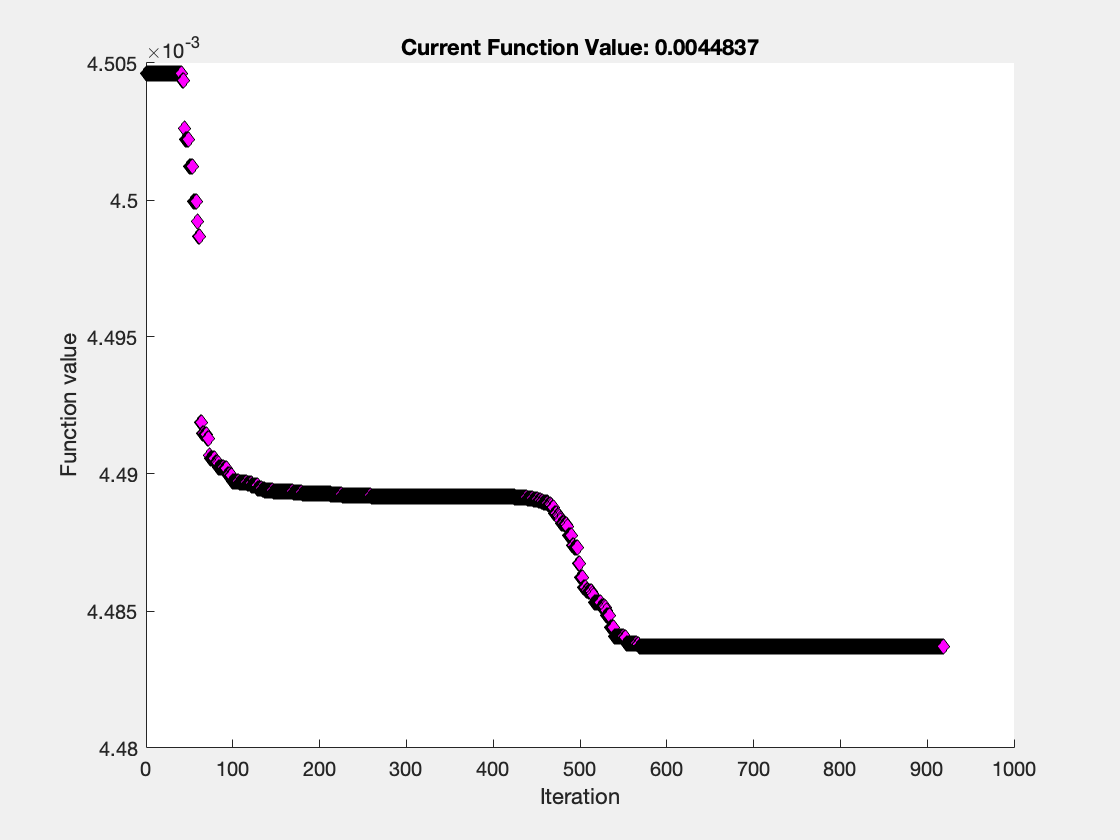

% tic
% 
% JJ = @(param) J(param, data, h,time,init,tau,c);
% 
% % options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);
% 
% x0 = [2.0187*(10^-7),1.2535*(10^-7),1.42261,1.56561,42.77631622*(10^3),0.03931];
% [x,fval] = fminsearch(JJ,x0,options);

% x

x = 1.0e+04 *

    0.0000    0.0000    0.0001    0.0002    4.2408    0.0000


% 
% toc

Elapsed time is 65.124073 seconds.


% % +-10% error

fval = 0.0045

% plot(time, pred_logV(x,time,init, 7,23), ...
%     time,pred_logV(x0,time,init, 7,23), ...
%     time,pred_logV(xx,time,init, 7,23))
% 
% disp([JJ(x),JJ(x0),JJ(xx)]);
% hold on;
% scatter(data.dpi,data.log_vRNA);
% hold off;
% legend({'x','x0','xx'},'Location','southwest')

size(x1(1:end-1))

ans =      1     6


function out=beta(t,tau,k,beta_0,beta_ifty)
    if t <= tau
        out = beta_0;
    else
        out = beta_ifty+(beta_0-beta_ifty)*exp(-k*(t-tau));
    end
end


function out = pred_logV(param, time, init,tau,c)
    beta_0=param(1);
    beta_ifty=param(2);
    k = param(3);
    dlt = param(4);
    p = param(5);
    d = param(6);
    
    f = @(t,x) [d*(10^4-x(1))-beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3);...
            beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-c*x(3) ];
  
    [t,xa] = ode45(f,time,init);
    out = log10(xa(:,3));
    
end


function out=J(param,data,h,time,init,tau,c)
    pred = pred_logV(param, time, init,tau,c);

    num = size(data,1);
    sum = 0;
    for i = 1:num
        day = data(i,1);
        pred_logv = pred(day/h+1);
        
        sum = sum + (pred_logv - data(i,2))^2;
    end 
    
   out = sum/num;
end 

function out=best_param(data,x0)
    h = 0.01;
    time = 0:h:80; 
    init = [10^4 0 10^-3];
    c = 23;
    tau = x0(end);

    % options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);
    JJ = @(param) J(param, data, h,time,init,tau,c);
    out = fminsearchbnd(JJ,x0(1:end-1),[0,0,0,0,0,0]);
end 






function [x,fval,exitflag,output] = fminsearchbnd(fun,x0,LB,UB,options,varargin)
% FMINSEARCHBND: FMINSEARCH, but with bound constraints by transformation
% usage: x=FMINSEARCHBND(fun,x0)
% usage: x=FMINSEARCHBND(fun,x0,LB)
% usage: x=FMINSEARCHBND(fun,x0,LB,UB)
% usage: x=FMINSEARCHBND(fun,x0,LB,UB,options)
% usage: x=FMINSEARCHBND(fun,x0,LB,UB,options,p1,p2,...)
% usage: [x,fval,exitflag,output]=FMINSEARCHBND(fun,x0,...)
% 
% arguments:
%  fun, x0, options - see the help for FMINSEARCH
%
%  LB - lower bound vector or array, must be the same size as x0
%
%       If no lower bounds exist for one of the variables, then
%       supply -inf for that variable.
%
%       If no lower bounds at all, then LB may be left empty.
%
%       Variables may be fixed in value by setting the corresponding
%       lower and upper bounds to exactly the same value.
%
%  UB - upper bound vector or array, must be the same size as x0
%
%       If no upper bounds exist for one of the variables, then
%       supply +inf for that variable.
%
%       If no upper bounds at all, then UB may be left empty.
%
%       Variables may be fixed in value by setting the corresponding
%       lower and upper bounds to exactly the same value.
%
% Notes:
%
%  If options is supplied, then TolX will apply to the transformed
%  variables. All other FMINSEARCH parameters should be unaffected.
%
%  Variables which are constrained by both a lower and an upper
%  bound will use a sin transformation. Those constrained by
%  only a lower or an upper bound will use a quadratic
%  transformation, and unconstrained variables will be left alone.
%
%  Variables may be fixed by setting their respective bounds equal.
%  In this case, the problem will be reduced in size for FMINSEARCH.
%
%  The bounds are inclusive inequalities, which admit the
%  boundary values themselves, but will not permit ANY function
%  evaluations outside the bounds. These constraints are strictly
%  followed.
%
%  If your problem has an EXCLUSIVE (strict) constraint which will
%  not admit evaluation at the bound itself, then you must provide
%  a slightly offset bound. An example of this is a function which
%  contains the log of one of its parameters. If you constrain the
%  variable to have a lower bound of zero, then FMINSEARCHBND may
%  try to evaluate the function exactly at zero.
%
%
% Example usage:
% rosen = @(x) (1-x(1)).^2 + 105*(x(2)-x(1).^2).^2;
%
% fminsearch(rosen,[3 3])     % unconstrained
% ans =
%    1.0000    1.0000
%
% fminsearchbnd(rosen,[3 3],[2 2],[])     % constrained
% ans =
%    2.0000    4.0000
%
% See test_main.m for other examples of use.
%
%
% See also: fminsearch, fminspleas
%
%
% Author: John D'Errico
% E-mail: woodchips@rochester.rr.com
% Release: 4
% Release date: 7/23/06
% size checks
xsize = size(x0);
x0 = x0(:);
n=length(x0);
if (nargin<3) || isempty(LB)
  LB = repmat(-inf,n,1);
else
  LB = LB(:);
end
if (nargin<4) || isempty(UB)
  UB = repmat(inf,n,1);
else
  UB = UB(:);
end
if (n~=length(LB)) || (n~=length(UB))
  error 'x0 is incompatible in size with either LB or UB.'
end
% set default options if necessary
if (nargin<5) || isempty(options)
  options = optimset('fminsearch');
end
% stuff into a struct to pass around
params.args = varargin;
params.LB = LB;
params.UB = UB;
params.fun = fun;
params.n = n;
% note that the number of parameters may actually vary if 
% a user has chosen to fix one or more parameters
params.xsize = xsize;
params.OutputFcn = [];
% 0 --> unconstrained variable
% 1 --> lower bound only
% 2 --> upper bound only
% 3 --> dual finite bounds
% 4 --> fixed variable
params.BoundClass = zeros(n,1);
for i=1:n
  k = isfinite(LB(i)) + 2*isfinite(UB(i));
  params.BoundClass(i) = k;
  if (k==3) && (LB(i)==UB(i))
    params.BoundClass(i) = 4;
  end
end
% transform starting values into their unconstrained
% surrogates. Check for infeasible starting guesses.
x0u = x0;
k=1;
for i = 1:n
  switch params.BoundClass(i)
    case 1
      % lower bound only
      if x0(i)<=LB(i)
        % infeasible starting value. Use bound.
        x0u(k) = 0;
      else
        x0u(k) = sqrt(x0(i) - LB(i));
      end
      
      % increment k
      k=k+1;
    case 2
      % upper bound only
      if x0(i)>=UB(i)
        % infeasible starting value. use bound.
        x0u(k) = 0;
      else
        x0u(k) = sqrt(UB(i) - x0(i));
      end
      
      % increment k
      k=k+1;
    case 3
      % lower and upper bounds
      if x0(i)<=LB(i)
        % infeasible starting value
        x0u(k) = -pi/2;
      elseif x0(i)>=UB(i)
        % infeasible starting value
        x0u(k) = pi/2;
      else
        x0u(k) = 2*(x0(i) - LB(i))/(UB(i)-LB(i)) - 1;
        % shift by 2*pi to avoid problems at zero in fminsearch
        % otherwise, the initial simplex is vanishingly small
        x0u(k) = 2*pi+asin(max(-1,min(1,x0u(k))));
      end
      
      % increment k
      k=k+1;
    case 0
      % unconstrained variable. x0u(i) is set.
      x0u(k) = x0(i);
      
      % increment k
      k=k+1;
    case 4
      % fixed variable. drop it before fminsearch sees it.
      % k is not incremented for this variable.
  end
  
end
% if any of the unknowns were fixed, then we need to shorten
% x0u now.
if k<=n
  x0u(k:n) = [];
end
% were all the variables fixed?
if isempty(x0u)
  % All variables were fixed. quit immediately, setting the
  % appropriate parameters, then return.
  
  % undo the variable transformations into the original space
  x = xtransform(x0u,params);
  
  % final reshape
  x = reshape(x,xsize);
  
  % stuff fval with the final value
  fval = feval(params.fun,x,params.args{:});
  
  % fminsearchbnd was not called
  exitflag = 0;
  
  output.iterations = 0;
  output.funcCount = 1;
  output.algorithm = 'fminsearch';
  output.message = 'All variables were held fixed by the applied bounds';
  
  % return with no call at all to fminsearch
  return
end
% Check for an outputfcn. If there is any, then substitute my
% own wrapper function.
if ~isempty(options.OutputFcn)
  params.OutputFcn = options.OutputFcn;
  options.OutputFcn = @outfun_wrapper;
end
% now we can call fminsearch, but with our own
% intra-objective function.
[xu,fval,exitflag,output] = fminsearch(@intrafun,x0u,options,params);
% undo the variable transformations into the original space
x = xtransform(xu,params);
% final reshape to make sure the result has the proper shape
x = reshape(x,xsize);
% Use a nested function as the OutputFcn wrapper
  function stop = outfun_wrapper(x,varargin);
    % we need to transform x first
    xtrans = xtransform(x,params);
    
    % then call the user supplied OutputFcn
    stop = params.OutputFcn(xtrans,varargin{1:(end-1)});
    
  end
end % mainline end
% ======================================
% ========= begin subfunctions =========
% ======================================
function fval = intrafun(x,params)
% transform variables, then call original function
% transform
xtrans = xtransform(x,params);
% and call fun
fval = feval(params.fun,reshape(xtrans,params.xsize),params.args{:});
end % sub function intrafun end
% ======================================
function xtrans = xtransform(x,params)
% converts unconstrained variables into their original domains
xtrans = zeros(params.xsize);
% k allows some variables to be fixed, thus dropped from the
% optimization.
k=1;
for i = 1:params.n
  switch params.BoundClass(i)
    case 1
      % lower bound only
      xtrans(i) = params.LB(i) + x(k).^2;
      
      k=k+1;
    case 2
      % upper bound only
      xtrans(i) = params.UB(i) - x(k).^2;
      
      k=k+1;
    case 3
      % lower and upper bounds
      xtrans(i) = (sin(x(k))+1)/2;
      xtrans(i) = xtrans(i)*(params.UB(i) - params.LB(i)) + params.LB(i);
      % just in case of any floating point problems
      xtrans(i) = max(params.LB(i),min(params.UB(i),xtrans(i)));
      
      k=k+1;
    case 4
      % fixed variable, bounds are equal, set it at either bound
      xtrans(i) = params.LB(i);
    case 0
      % unconstrained variable.
      xtrans(i) = x(k);
      
      k=k+1;
  end
end
end % sub function xtransform end
